## Probleme

### Problema 1

#### Legendre

Implementare

#### Cebisev #1

Implementare

#### Cebisev #2

Implementare

#### Jacobi

Implementare

#### Laguerre 

Implementare

#### Hermite

Implementare

## Problema 2

tol=1e-7;
n0=5;
[g_n1,g_c1]=Gauss_Legendre(n0);


$$\int_{-1}^1 {\textrm{sinx}}^2 \textrm{dx}$$


f1=@(x) sin(x.^2);
v1(1)=vquad(g_n1,g_c1,f1);
k=1;
for n=n0+1:4*n0
    [gn,gc]=Gauss_Legendre(n);
    k=k+1;
    v1(k)=vquad(gn,gc,f1);
    if abs(v1(k)-v1(k-1)) < tol
        disp([gn,gc'])
        fprintf('I1(%2d)=%12.8f\n',n,v1(k))
        break;
    end
end

   -0.9603    0.1012
   -0.7967    0.2224
   -0.5255    0.3137
   -0.1834    0.3627
    0.1834    0.3627
    0.5255    0.3137
    0.7967    0.2224
    0.9603    0.1012



I1( 8)=  0.62053660



$$\int_{-1}^1 {\textrm{cosx}}^2 \textrm{dx}$$


f2=@(x) cos(x.^2);
v2(1)=vquad(g_n1,g_c1,f2);
k=1;
for n=n0+1:4*n0
    [gn,gc]=Gauss_Legendre(n);
    k=k+1;
    v2(k)=vquad(gn,gc,f2);
    if abs(v2(k)-v2(k-1)) < tol
        fprintf('I2(%2d)=%12.8f\n',n,v2(k))
        break;
    end
end

I2( 8)=  1.80904847


Verificare simbolică

syms t rest f(t) xi
vpa(int(sin(t^2),t,-1,1))

$$ans = 0.62053660344676220361630484633079$$

vpa(int(cos(t^2),t,-1,1))

$$ans = 1.8090484758005441629495767336651$$

Verificare cu formula restului

po=legendreP(n,t);
c=coeffs(po,'All');
po=po/c(1)

$$po = t^{8}-\frac{28\,t^{6}}{15}+\frac{14\,t^{4}}{13}-\frac{28\,t^{2}}{143}+\frac{7}{1287}$$

rest=1/factorial(2*n)*int(po^2,t,-1,1)*subs(diff(f(t),t,n),t,xi);
[rest,vpa(rest)]

$$ans = \left(\begin{array}{cc} \frac{7573384136472607\,\frac{\partial^{8}}{\partial \xi^{8}}f\left(\xi \right)}{3404126326545748309514119859404800} & 0.000000000000000002224765889977270125691636407827\,\frac{\partial^{8}}{\partial \xi^{8}}f\left(\xi \right) \end{array}\right)$$

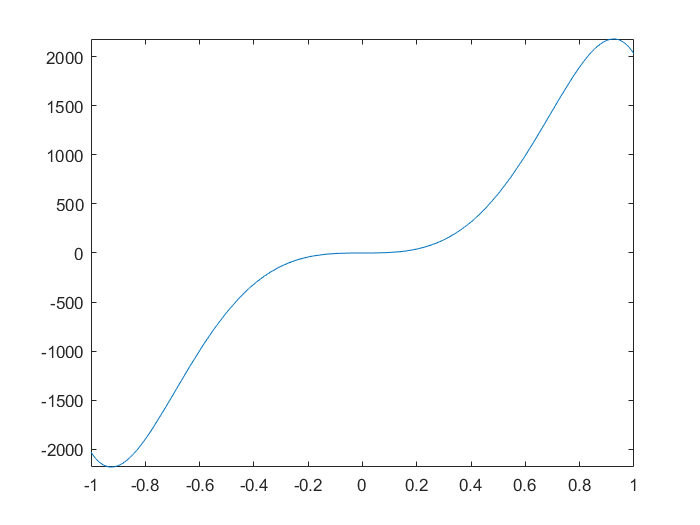

fplot(diff(sin(t^2),t,7),[-1,1])

## Problema 3

clear
syms t f(t)
R=diff(f(t),t,20)/factorial(20)*int((1-t^2)^(-sym(1)/sym(2))*chebyshevT(10,t)^2,t,-1,1)

$$R = \frac{\pi \,\frac{\partial^{20}}{\partial t^{20}}f\left(t\right)}{4865804016353280000}$$

f=@(x) x.*exp(-x.^2)

f = function_handle with value:
    @(x)x.*exp(-x.^2)


[gn,gc]=Gauss_Cheb1(10);
vi=vquad(gn,gc,f)

vi = 8.3267e-17

## Problema 4

D10=diff(exp(-t^2),t,20)

$$D10 = 670442572800\,{\mathrm{e}}^{-t^{2}}-13408851456000\,t^{2}\,{\mathrm{e}}^{-t^{2}}+40226554368000\,t^{4}\,{\mathrm{e}}^{-t^{2}}-42908324659200\,t^{6}\,{\mathrm{e}}^{-t^{2}}+21454162329600\,t^{8}\,{\mathrm{e}}^{-t^{2}}-5721109954560\,t^{10}\,{\mathrm{e}}^{-t^{2}}+866834841600\,t^{12}\,{\mathrm{e}}^{-t^{2}}-76205260800\,t^{14}\,{\mathrm{e}}^{-t^{2}}+3810263040\,t^{16}\,{\mathrm{e}}^{-t^{2}}-99614720\,t^{18}\,{\mathrm{e}}^{-t^{2}}+1048576\,t^{20}\,{\mathrm{e}}^{-t^{2}}$$

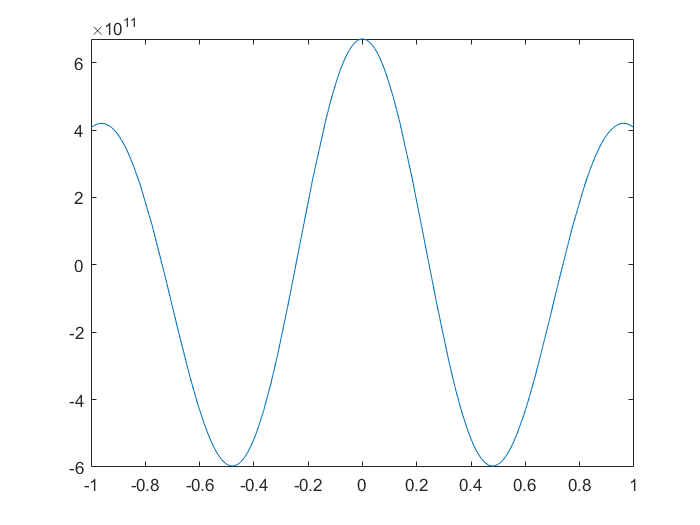

fplot(D10,[-1,1])

Md=subs(D10,t,sym(0))

$$Md = 670442572800$$

R=1/factorial(20)*int(sqrt(1-t^2)*chebyshevU(10,t)^2,t,-1,1)*Md

$$R = \frac{5589288360794662244495775\,\pi }{40564819207303340847894502572032}$$

vpa(R)

$$ans = 0.00000043286935813351427847312309828726$$

f=@(x) exp(-x.^2);
[gn,gc]=Gauss_Cheb1(10);
vi=vquad(gn,gc,f)

vi = 2.0264

## Problema 5

f = @(x) exp(-x).*sin(x);
n0=5;
[g_nodes, g_coef] = Gauss_Legendre(n0);
v(1) = vquad(g_nodes, g_coef, f);
k = 2;
for grd=n0+1:4*n0
    [g_nodes, g_coef] = Gauss_Legendre(grd);
    v(k) = vquad(g_nodes, g_coef, f);
    
    if abs(v(k)-v(k-1)) < 1e-8
        fprintf('I(%2d)=%12.8f\n',grd,v(k))
        break;
    end
    
    k = k+1;
end

I( 7)= -0.66349367


f = @(x) exp(-x).*cos(x);
n0=5;
[g_nodes, g_coef] = Gauss_Legendre(n0);
v(1) = vquad(g_nodes, g_coef, f);
k = 2;
for grd=n0+1:4*n0
    [g_nodes, g_coef] = Gauss_Legendre(grd);
    v(k) = vquad(g_nodes, g_coef, f);
    
    if abs(v(k-1)-v(k)) < 1e-8
        fprintf('I(%2d)=%12.8f\n',grd,v(k))
        break;
    end
    
    k = k+1;
end

I( 6)=  1.93342150


## Problema 6

f = @(x) exp(-(x.^2)).*sin(x);
n0=5;
[g_nodes, g_coef] = Gauss_Hermite(n0);
v(1) = vquad(g_nodes, g_coef, f);
k = 2;
for grd=n0+1:4*n0
    [g_nodes, g_coef] = Gauss_Hermite(grd);
    v(k) = vquad(g_nodes, g_coef, f);
    
    if v(k-1)-v(k) < 1e-8
        fprintf('I(%2d)=%12.8f\n',grd,v(k))
        break;
    end
    
    k = k+1;
end

I( 6)=  0.00000000


f = @(x) exp(-(x.^2)).*cos(x);
n0=5;
[g_nodes, g_coef] = Gauss_Hermite(n0);
v(1) = vquad(g_nodes, g_coef, f);
k = 2;
for grd=n0+1:4*n0
    [g_nodes, g_coef] = Gauss_Hermite(grd);
    v(k) = vquad(g_nodes, g_coef, f);
    
    if v(k-1)-v(k) < 1e-8
        fprintf('I(%2d)=%12.8f\n',grd,v(k))
        break;
    end
    
    k = k+1;
end

I( 7)=  1.10901948


## Problema 7

f = @(x) sqrt(1./sin(x));
n0=5;
a=0;b=pi/2;
[g_nodes, g_coef] = Gauss_Jacobi(n0,a,b);
v(1) = vquad(g_nodes, g_coef, f);
k = 2;
for grd=n0+1:4*n0
    [g_nodes, g_coef] = Gauss_Jacobi(grd,a,b);
    v(k) = vquad(g_nodes, g_coef, f);
    
    if v(k-1)-v(k) < 1e-9
        fprintf('I(%2d)=%12.8f\n',grd,v(k))
        break;
    end
    
    k = k+1;
end

I( 7)=  3.17804263


function [g_nodes,g_coeff]=Gauss_Cheb1(n)
%GAUSS_CEB1 - Gauss-Chebyshev #1 nodes and coefficients
    g_coeff=pi/n*ones(1,n);
    g_nodes=cos(pi*([1:n]'-0.5)/n);
end

function [g_nodes,g_coeff]=Gauss_Cheb2(n)
%GAUSS_CHEB2 - Gauss-Chebyshev #2 nodes and coefficients
    beta=[pi/2,1/4*ones(1,n-1)];
    alpha=zeros(n,1);
    [g_nodes,g_coeff]=Gaussquad(alpha,beta);
end

function [g_nodes,g_coeff]=Gauss_Hermite(n)
%GAUSS_HERMITE - Gauss-Hermite nodes and coefficients
    beta=[sqrt(pi),[1:n-1]/2];
    alpha=zeros(n,1);
    [g_nodes,g_coeff]=Gaussquad(alpha,beta);
end

function [g_nodes,g_coeff]=Gauss_Jacobi(n,a,b)
%Gauss-Jacobi - Gauss-Jacobi nodes and coefficients
%weight function w(t)=(1-t)^a(1+t)^b
    if nargin<2, a=0; end;  if nargin<3, b=a; end
    if((n<=0)||(a<=-1)||(b<=-1))
        error('parameter(s) out of range')
    end
    a0=(b-a)/(b+a+2);
    b0=2^(a+b+1)*gamma(a+1)*gamma(b+1)/gamma(a+b+2);
    if n==1
        alpha=a0; bet=b0;
    else
        k1=1:n-1;
        k2=2:n-1;
        b1=4*(1+a)*(1+b)/((2+a+b)^2*(3+a+b));
        if a==b
            alpha=zeros(1,n);
        else
            alpha=[a0,(b^2-a^2)./(2*k1+a+b)./(2*k1+a+b+2)];
        end
        bet=[b0,b1,4*k2.*(k2+a+b).*(k2+a).*...
            (k2+b)./(2*k2+a+b-1)./(2*k2+a+b).^2./(2*k2+a+b+1)];
    end
    [g_nodes,g_coeff]=Gaussquad(alpha,bet);
end

function [g_nodes,g_coeff]=Gauss_Jacobimodificat(n,a,b)
%Gauss-Jacobimodificat - Gauss-Jacobi nodes and coefficients
%weight function w(t)=(1-t)^a(1+t)^b
    k1=1:n-1;
    k2=2:n-1;
    %rec. relation coeffs
    bet0=2^(a+b+1)*gamma(a+1)*gamma(b+1)/gamma(a+b+2);
    bet1=4*(1+a)*(1+b)/((2+a+b)^2)/(3+a+b);
    bet=[bet0, bet1, 4*k2.*(k2+a+b).*(k2+a).*...
            (k2+b)./(2*k2+a+b-1)./(2*k2+a+b).^2./(2*k2+a+b+1)];
    if a==b
        alpha=zeros(1,n);
    else
        %alpha1=(b^2-a^2)/(a+b);
        
        alpha=[(b-a)./(a+b+2),(b^2-a^2)./(2*k1+a+b)./(2*k1+a+b+2)];
    end
    %alpha=[alpha1,(b^2-a^2)./(2*k+a+b)./(2*k+a+b+2)];
    [g_nodes,g_coeff]=Gaussquad(alpha,bet);
end

function [g_nodes,g_coeff]=Gauss_Laguerre(n,a)
%GAUSS_LAGUERRE - Gauss-Laguerre nodes and coefficients
    if nargin<2, a=0; end
    k=1:n-1;
    alpha=[a+1, 2*k+a+1];
    beta=[gamma(1+a),k.*(k+a)];
    [g_nodes,g_coeff]=Gaussquad(alpha,beta);
end

function [g_nodes,g_coeff]=Gauss_Legendre(n)
%GAUSS-LEGENDRE - Gauss-Legendre nodes and coefficients
    beta=[2,(4-(1:n-1).^(-2)).^(-1)]; 
    alpha=zeros(n,1);
    [g_nodes,g_coeff]=Gaussquad(alpha,beta);
end

function [g_nodes,g_coeff]=Gaussquad(alpha,beta)
%GAUSSQUAD - generate Gaussian quadrature formula
%computes nodes and coefficients for 
%Gauss rules given alpha and beta
%method - Jacobi matrix
    n=length(alpha); rb=sqrt(beta(2:n));
    J=diag(alpha)+diag(rb,-1)+diag(rb,1);
    [v,d]=eig(J);
    g_nodes=diag(d); 
    g_coeff=beta(1)*v(1,:).^2;
end

function I=vquad(g_nodes,g_coeff,f)
    I=g_coeff*f(g_nodes);
end